% 2024-05-09
% Reference: F. Ferraguti et al., “Safety and Efficiency in Robotics: The Control Barrier Functions Approach,” IEEE Robot. Automat. Mag., vol. 29, no. 3, pp. 139–151, Sep. 2022, doi: 10.1109/MRA.2022.3174699.

clc
clear
close all

## CBF for 2 Dof


$$\dot{x} = u$$



$$f\left(x\right)={\left\lbrack 0\;0\right\rbrack }^T ,g\left(x\right)=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$



$$h\left(x\right)=||x-x_{\textrm{obs}} ||^2 -R^2$$



$$q\left(x\right)=2{\left(x-x_{\textrm{obs}} \right)}^T$$


## Model parameters and initial conditions

R = 0.25;
x_obs = [1; 1];
x_init = [0; 0];
gamma = 20;

Tf = 5; % Duration
Ts = 0.001; % Sample time

## Simulink model

mdl = 'CBF_for_2Dof';
open_system(mdl)

out = sim(mdl);

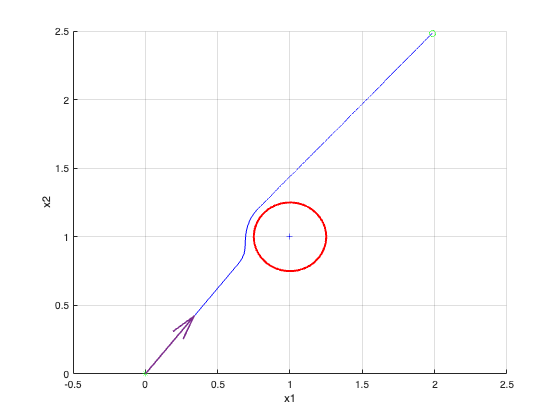


logData = out.logsout;
size_of_time = size(logData{2}.Values.Data, 1);
x1 = zeros(size_of_time, 1);
x2 = zeros(size_of_time, 1);
control_input = zeros(size_of_time, 2);
des_input = zeros(size_of_time, 2);
hx = zeros(size_of_time, 1);

for ct = 1:size_of_time
    x1(ct) = logData{1}.Values.Data(ct, 1);
    x2(ct) = logData{1}.Values.Data(ct, 2);
    control_input(ct, :) = logData{2}.Values.Data(ct, :);
    des_input(ct, :) = logData{3}.Values.Data(:,:,ct)';
    hx(ct) = logData{4}.Values.Data(ct);
end

% Plot
figure('Name','Tracking with Constraint');
viscircles(x_obs', R);
%hold on
%plot(x_obs(1), x_obs(2), 'Color','b', 'Marker','+');
hold on
plot(x1, x2, 'b'), grid
xlabel('x1')
ylabel('x2')
hold on
plot(x1(1),x2(1),'g*')
hold on
plot(x1(end),x2(end),'go')
hold on
quiver(x1(1), x2(1), x1(20), x2(20), 10, 'LineWidth', 1.5, 'MaxHeadSize',2)
plot(x_obs(1), x_obs(2), 'Color','b', 'Marker','+')
xlim([-0.5 2.5])
ylim([0 2.5])

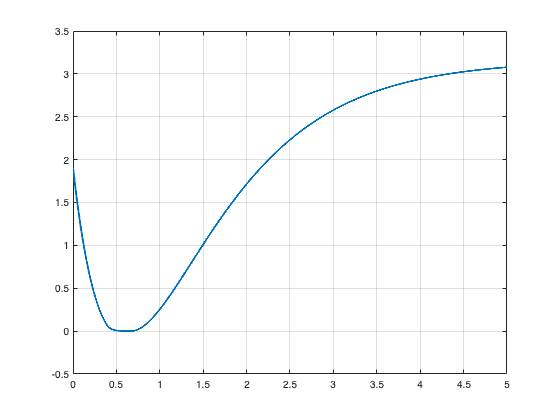


figure('Name','The values of the CBF');
plot(out.tout(1:size_of_time), hx, 'LineWidth', 2), grid
xlim([0 5])
ylim([-0.5 3.5])

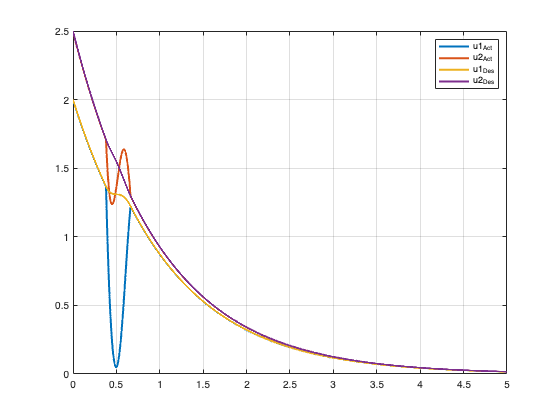


figure('Name','Input');
plot(out.tout(1:size_of_time), control_input, 'LineWidth',2)
hold on
plot(out.tout(1:size_of_time), des_input, 'LineWidth', 2)
grid
legend('u1_{Act}', 'u2_{Act}', 'u1_{Des}', 'u2_{Des}')